# Computational Methods in Ordinary Differential Equations

## Stability of explicit Runge-Kutta method

The stability of a Runge-Kutta numerical method is examined by determining the stability function of the method when used to compute the solution to the test problem $y'=\lambda y$.

The stability function, $R(z)$, is a function of $z=h\lambda$ such that


$$y_{n+1} = R(z) y_{n}$$


For an Explicit Runge-Kutta method (ERK) it can be shown that the stability function is


$$R(z) = 1 + \mathbf{b} \cdot \mathbf{1} z + \sum_{k=2}^{s} \mathbf{b} \cdot A^{k-2} \cdot \mathbf{c} z^k$$


where $\mathbf{1}=(1, 1, \ldots, 1)$. The order of an ERK can be determined by the number of terms that $R(z)$ agrees with the series expansion of $\exp(z)$ which is the solution to the test problem.


$$\exp(z) = \sum_{k=0}^\infty \frac{1}{k!}z^k = 1 + z + \frac{1}{2}z^2 + \frac{1}{6}z^3 + \frac{1}{24}k^4 + \cdots$$


#### Example

Determine the stability function for the following Runge-Kutta method and hences find its order.


$$y_{n+1} = y_n + h\left(\frac{7}{24}k_1 + \frac{1}{4}k_2 + \frac{1}{3}k_3 + \frac{1}{8}k_4\right), \\
\,\,\,\,\,\,\,k_1 = f(t_n, y_n), \\
\,\,\,\,\,\,\,k_2 = f\left( t_n + \frac{1}{2}h, y_n + \frac{1}{2}hk_1\right), \\
\,\,\,\,\,\,\,k_3 = f\left(t_n + \frac{3}{4}h, y_n + h\frac{3}{4}hk_2 \right), \\
\,\,\,\,\,\,\,k_4 = f\left(t_n + h, y_n + h\left(\frac{2}{9}k_1 + \frac{1}{3}k_2 + \frac{4}{9}k_3\right)\right).$$


% Define ERK method
A = [ 0, 0, 0, 0 ; 1/2, 0, 0, 0 ; 0, 3/4, 0, 0 ; 2/9, 1/3, 4/9, 0 ];
b = [ 7/24, 1/4, 1/3, 1/8 ];
c = [ 0, 1/2, 3/4, 1 ];

% Determine stability function
Rz = 'R(z) = 1' ;
for k = 1 : length(b)
    
    % Calculate coefficient of z^k
    if k == 1
        coeff = b * ones(length(b), 1);
    else
        coeff = b * A^(k-2) * c';
    end
    
    % Append kth term to Rz
    Rz = join([Rz, sprintf(' + %1s z^%1i', strtrim(rats(coeff)), k)]);
end

% Output stability function
disp(Rz)

R(z) = 1 + 1 z^1 + 1/2 z^2 + 3/16 z^3 + 1/48 z^4


So the stability function is


$$R(z) = 1 + z + \frac{1}{2}z^2 + \frac{3}{16}z^3 + \frac{1}{48}z^4$$


which agrees to the series expansion of $\exp(z)$ upto and including the $z^2$ term. Therefore this is a second-order ERK method.

### Absolute stability

The region of absolute stability is defined by the values of $z\in\mathbb{C}$ for which the absolute value of the stability function is less than or equal to 1


$$\text{region of absolute stability} = \{ z : z \in \mathbb{C}, |z| \leq 1 \}.$$


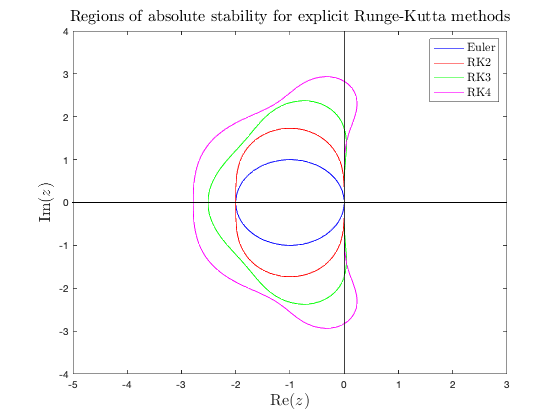

% Generate z values
x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);
[X, Y] = meshgrid(x, y);
Z = X + Y * 1i;

% Determine ERK stability functions
Rz1 = 1 + Z;
Rz2 = Rz1 + Z.^2 / 2;
Rz3 = Rz2 + Z.^3 / 6;
Rz4 = Rz3 + Z.^4 / 24;

% Calculate absolute values
Rz1 = abs(Rz1);
Rz2 = abs(Rz2);
Rz3 = abs(Rz3);
Rz4 = abs(Rz4);

% Plot stability regions
hold on
contour(X, Y, Rz1, [1, 1], 'b')
contour(X, Y, Rz2, [1, 1], 'r')
contour(X, Y, Rz3, [1, 1], 'g')
contour(X, Y, Rz4, [1, 1], 'm')
plot([0, 0], [-10, 10], 'k-')
plot([-10, 10], [0, 0], 'k-')
hold off
axis([-5, 3, -4, 4])
box on

title('Regions of absolute stability for explicit Runge-Kutta methods', ...
    'FontSize', 16, 'Interpreter', 'latex')
xlabel('Re$(z)$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('Im$(z)$', 'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Euler', 'RK2', 'RK3', 'RK4');
set(leg, 'FontSize', 12, 'Interpreter', 'latex')